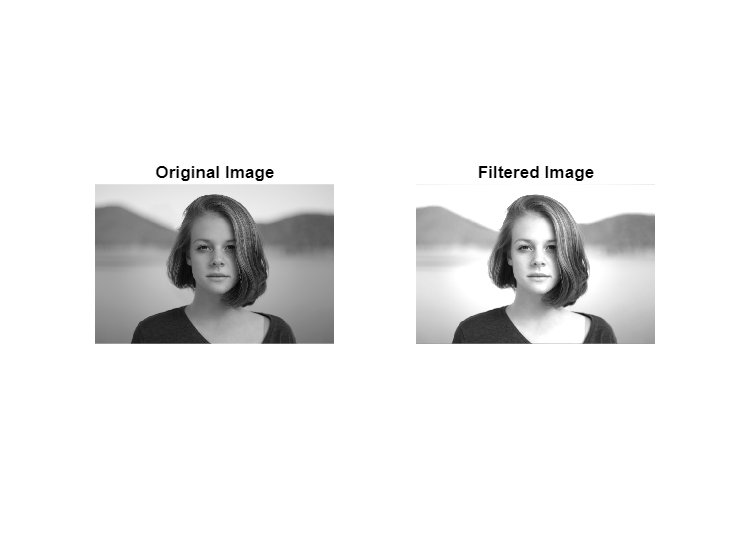

% Load image
img = imread('person.jpeg');

% Convert image to grayscale
gray_img = rgb2gray(img);

% Define filter
filter = [1 1 1; 1 5 1; 1 1 1]/9;

% Apply filter to image using convolution
filtered_img = conv2(double(gray_img), filter, 'same');

% Show original and filtered images side by side
figure;
subplot(1,2,1);
imshow(gray_img);
title('Original Image');
subplot(1,2,2);
imshow(uint8(filtered_img));
title('Filtered Image');